Experiments around with different ways of representing the traces.

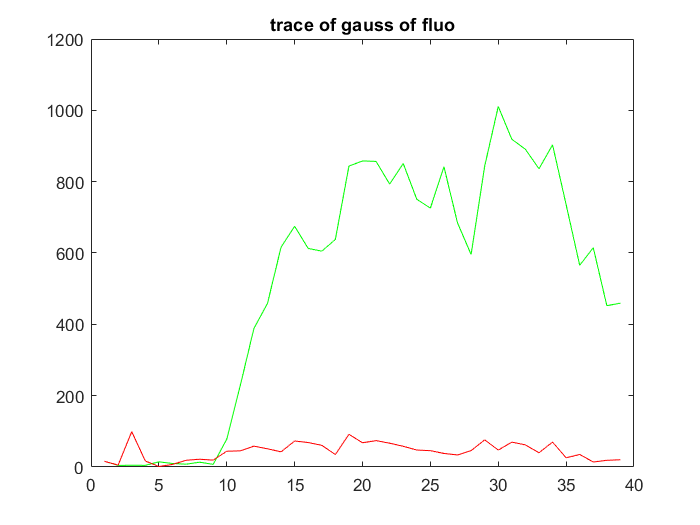

% plots actual traces
load('C:\Users\seanm\Desktop\garcia_lab_stuff\2-spot-cross-corr\dat\real_data\processed_data.mat');
i = 30;
data = preprocessed(i);

figure;
plot(data.greengauss, 'g');
hold on
plot(data.redgauss, 'r');
title('trace of gauss of fluo');

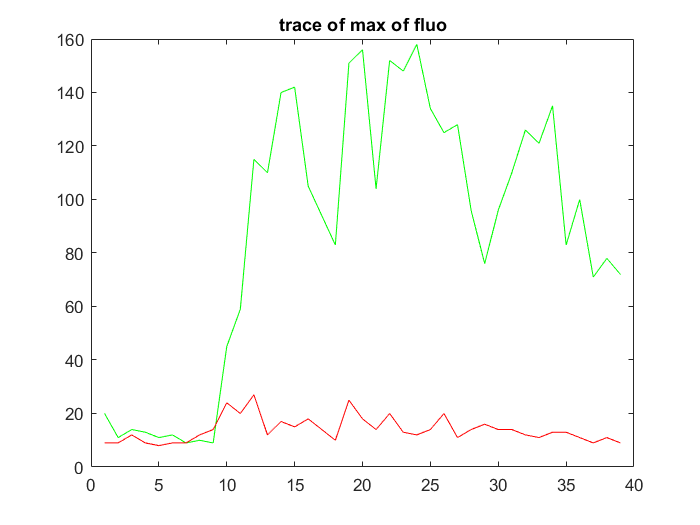


figure;
plot(data.greenmax, 'g');
hold on
plot(data.redmax, 'r');
title('trace of max of fluo');

Sets up the traces to perform the cross correlation on the data.

% sets up variables for cross correlation on real data

max_delay = 25;
project = 'PP7 Gauss auto corr';
trace1 = cell([1 length(preprocessed)]);
trace2 = cell([1 length(preprocessed)]);
for i = 1:length(preprocessed)
    trace1{i} = preprocessed(i).redgauss;
    trace2{i} = preprocessed(i).redgauss;
end

Plots individual synthetic data traces.

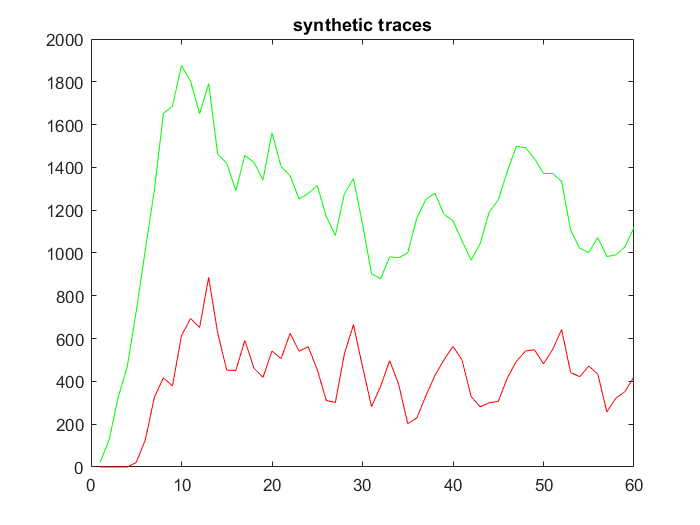

% plots synthetic data (manually add time delay)
tr = 35;
figure;
plot(data.green_traces{tr}, 'g');
hold on;
plot(data.red_traces{tr}, 'r');
title('synthetic traces');

Prepares synthetic data traces for cross correlation

% sets up variables for cross correlation on synthetic data

max_delay = 30;
project = 'eve-like-dT40w15w9n0';
trace1 = data.fluo_data{1};
trace2 = data.fluo_data{2};

Prepares individual spots for cross correlation data for inference.

% prepares the data for inference
load('C:\Users\seanm\Desktop\garcia_lab_stuff\elong_search\dat\real_data\processed_data.mat');

ParticlesOut = struct;
for i = 1:length(preprocessed)
    ParticlesOut(i).Fluo = preprocessed(i).greengauss;
    ParticlesOut(i).Time = preprocessed(i).times;
    ParticlesOut(i).APbin = 0;
end

save('green_data', 'ParticlesOut');

Interpolates MS2 data from window 11 (11 time steps) to window 8 (8 time steps)

%interpolates MS2 data from window 11 to window 8

newdT = 27.5;
for i = 1:length(ParticlesOut)
    start = double(int16(ParticlesOut(i).Time(1) / newdT + .5)) * newdT;
    finish = double(int16(ParticlesOut(i).Time(end) / newdT - .5)) * newdT;
    newTimes = start:newdT:finish;
    ParticlesOut(i).Fluo = interp1(ParticlesOut(i).Time, ParticlesOut(i).Fluo, newTimes);
    ParticlesOut(i).Time = newTimes;
end
save('green_data3.mat', 'ParticlesOut');

Plots individual synthetic data traces (same as earlier?)

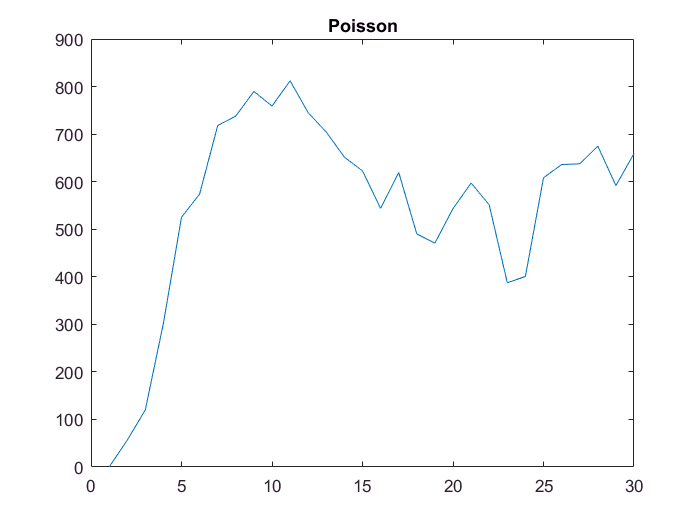

% plots synthetic data

load('fluo20K3w11_data.mat');
i = 25;
figure;
plot(data.fluo_data{i}(1:30));
title('Poisson');

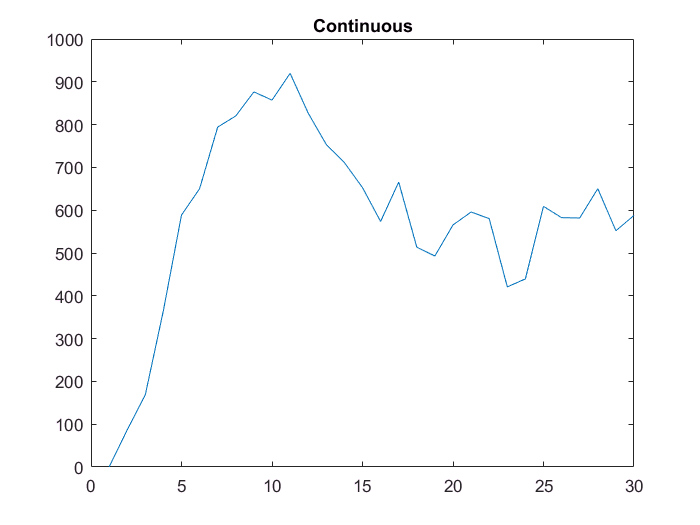

figure;
plot(data.old_fluo_data{i}(1:30));
title('Continuous');

Alternate way of analyzing traces.

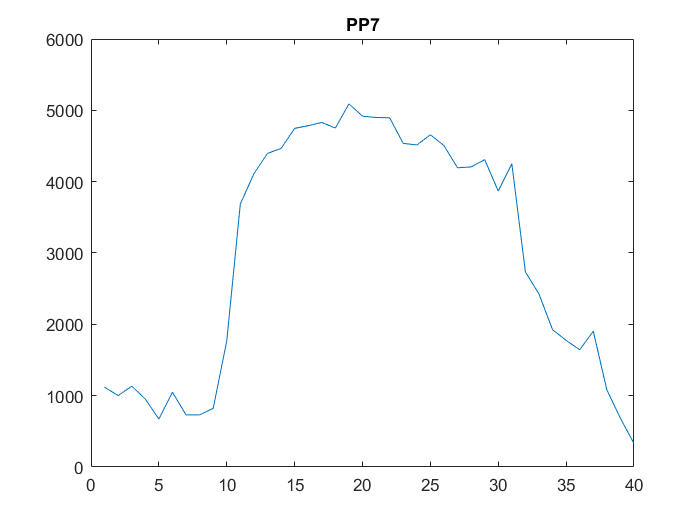

% adds MS2 traces together and adds PP7 traces together

load('C:\Users\seanm\Desktop\garcia_lab_stuff\2-spot-cross-corr\dat\real_data\processed_data.mat');
green = zeros(1, 40);
red = zeros(1, 40);
for i = 1:length(preprocessed)
    green = green + [preprocessed(i).greengauss zeros(1, 40 - length(preprocessed(i).greengauss))];
    red = red + [preprocessed(i).redgauss zeros(1, 40 - length(preprocessed(i).redgauss))];
end
figure;
plot(red);
title('PP7');

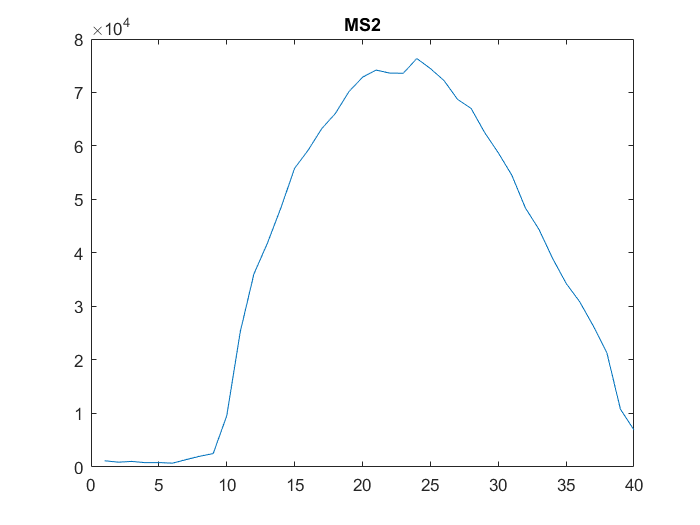

figure;
plot(green);
title('MS2');